clear all;
close all;
clc;

img_data = imread('cameraman.jpg');
imshow(img_data);
title('Original image');
img_data_vectorized = uint8(image_to_vector(img_data));
[zipped_1, info_1] = norm2huff(img_data);
[zipped_2, info_2] = norm2huff(img_data_vectorized);
img_data_unzipped = huff2norm(zipped_1, info_1);
img_data_vectorized_unzipped = huff2norm(zipped_2, info_2);
imshow(uint8(vector_to_image(img_data_unzipped, 512, 512)));
imshow(uint8(vector_to_image(img_data_vectorized_unzipped, 512, 512)));

clear all;
close all;
clc;

img_double = [211,231,56;174,78,55;198,201,2];
data_2 = [211,231,56,174,78,55,198,201,2];
[zipped_1, info_1] = norm2huff(uint8(img_double));
[zipped_2, info_2] = norm2huff(uint8(data_2));
% [zipped_3, info_3] = norm2huff(uint8(data_2));

clear all;
close all;
clc;

x = [2,2,2,2;3,0,3,3;4,44,5,4]
y = image_to_vector(x)
m = vector_to_image(y, 6, 2)

% Convert from double to uint8 is the process of quantization to 8bits
% When calculating PSNR, should I compare the result in uint8 to the result
% in double? Since after filtering, the data type is double, not uint8,
% another issue is the imshow for data type of double --> Scale?
clear all;
close all;
clc;

img = imread('cameraman.jpg');
imshow(img);
title('Original image');
filter = ones(8, 8)/64
img_double = double(img)
img_after_filter = filter2(filter, img_double)
img_after_filter_uint8 = uint8(img_after_filter)
imshow(img_after_filter, [min(min(img_after_filter)), max(max(img_after_filter))]);
title('After mean (in double)');
imshow(img_after_filter_uint8)
title('After mean (in uint8)');
% How to deal with the negative value here? Take absolutevalue?
img_difference = img_double - img_after_filter
img_difference_uint8 = uint8(img_difference)
imshow(img_difference_uint8);

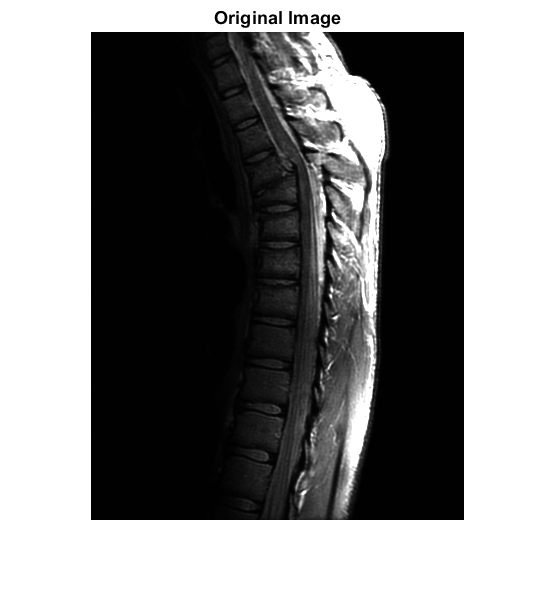

% A try for doing the mean operation with function 'blockproc'
clear all;
close all;
clc;

img = imread('spine.jpg');
imshow(img);
title('Original Image');

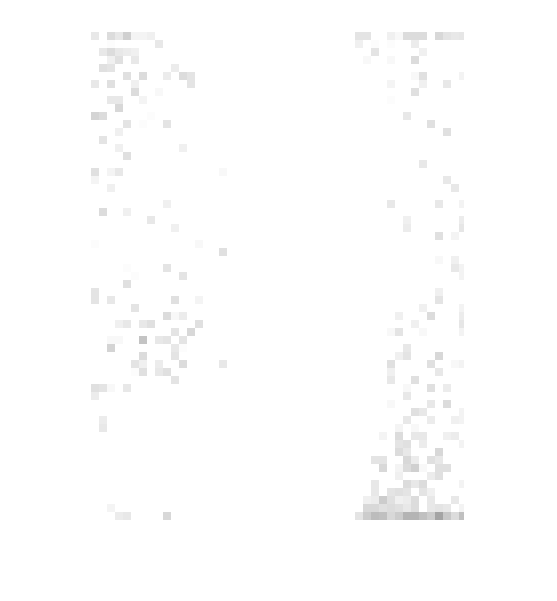

fun = @(block_struct) ...
   mean2(block_struct.data) * ones(size(block_struct.data));
mean_img_double = blockproc(img, [8 8], fun);
imshow(mean_img_double)


fun = @(block_struct) ...
   mean2(block_struct.data) * ones(size(block_struct.data));
mean_img_uint8 = blockproc(img, [8 8], fun);
imshow(mean_img_uint8)

% First calculate difference then convert to uint8
difference_double = mean_img_double - double(img);
difference_from_double_to_uint8 = uint8(difference_double);
% First convert to uint8 and then do difference
difference_uint8 = mean_img_uint8 - img;

Error using  - 
Integers can only be combined with integers of the same class, or scalar doubles.

% % % % % % % % % % % % % % % % % % % % % % 
% % %   Result seems to be same!  % % % % %
% % % % % % % % % % % % % % % % % % % % % % 

function img = vector_to_image(v, size_rows, size_columns)
img = zeros(size_rows, size_columns);
for i = 1:size_rows
    img(i,:) = v((i-1)*size_columns+1:i*size_columns);
end
end

function v = image_to_vector(img)
% N-by-N matrix
[size_rows, size_columns] = size(img);
v = zeros(1, size_rows*size_columns);
for i = 1:size_rows
    v((i-1)*size_columns+1:i*size_columns) = img(i,:);
end
end